## The purpose of this tutorial is to feature more advanced applications of the model.

clear; clc

addpath(genpath('.'));

### Simulate phase errors

Create AWG definition for a 100GHz demultiplexer on SOI

model = awg.AWG({
    'clad',     'SiO2'      % top cladding material
    'core',     'Si'        % core (guiding) material
    'subs',     'SiO2'      % bottom cladding material
    'lambda_c', 1.550       % design center wavelength
    'Ni',       1           % number of output channels
    'No',       9           % number of output channels
    'w',        0.450       % waveguide core width
    'h',        0.220       % waveguide core height (thickness)
    'N',        40          % number of arrayed waveguides
    'm',        75          % diffraction order
    'R',        130         % focal length (radius)
    'd',        2.5         % array aperture spacing (center-to-center)
    'g',        0.4         % gap width between waveguide apertures
    'do',       1.8         % output aperture spacing
    'wi',       1.5         % input aperture width
    'wo',       1.5         % output aperture width
    'L0',       20          % mininum array waveguide length
});

options = awg.SimulationOptions();
options.PhaseErrorVariance = .12;   % normal distribution noise
options.ModeType = 'gaussian';      % use faster gaussian approx


Perform a Monte Carlo analysis

for n = 1:10
    results = awg.spectrum(model, 1.55, .01, options, 'Samples', 100);
    
    measurements = awg.analyse(results);
    
    data(n,:) = measurements.Value;
end

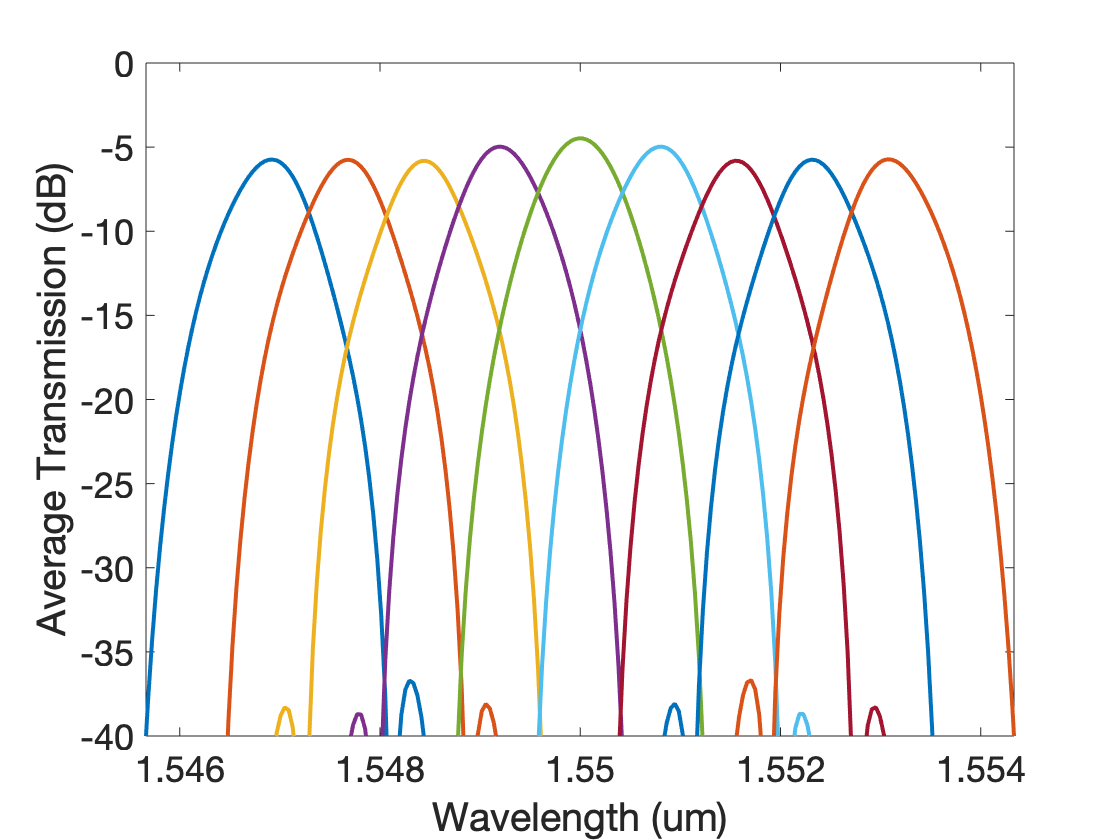


% plot measured performance
figure; clf;
hold on
boxplot(mat2cell(data', ones(1,size(data',1))))
legend(measurements.Row{:}, 'Location',"bestoutside")

xlabel('Measurement')
ylabel('Value')
set(gca,'FontSize',18)

% display measurement values
disp(table(mean(data,1)', std(data,1)', ...
    'VariableNames', ["Average","StdDev"], 'RowNames', [
    "Insertion loss (dB)"
    "Loss non-uniformity"
    "Channel spacing (nm)"
    "-3dB bandwidth (nm)"
    "-10dB bandwidth (nm)"
    "Adjacent channel Crosstalk (dB)"
    "Non-adjacent channel crosstalk (dB)"
]));

% plot spectrum with phase noise
figure
plot(results.wavelength, 10*log10(results.transmission), 'LineWidth', 2)
axis tight
ylim([-40,0])
xlabel('Trial')
ylabel('Value')
set(gca,'FontSize',18)